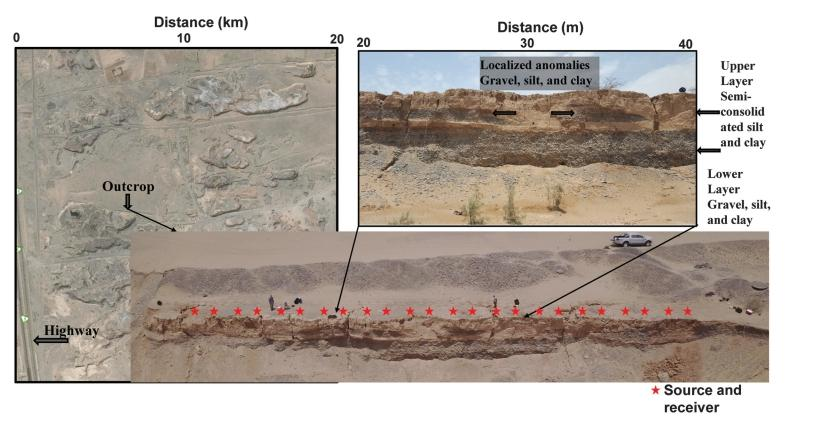

Inversion Depth = 10 m

load('datatest1.mat', 'seismo_v_d1')

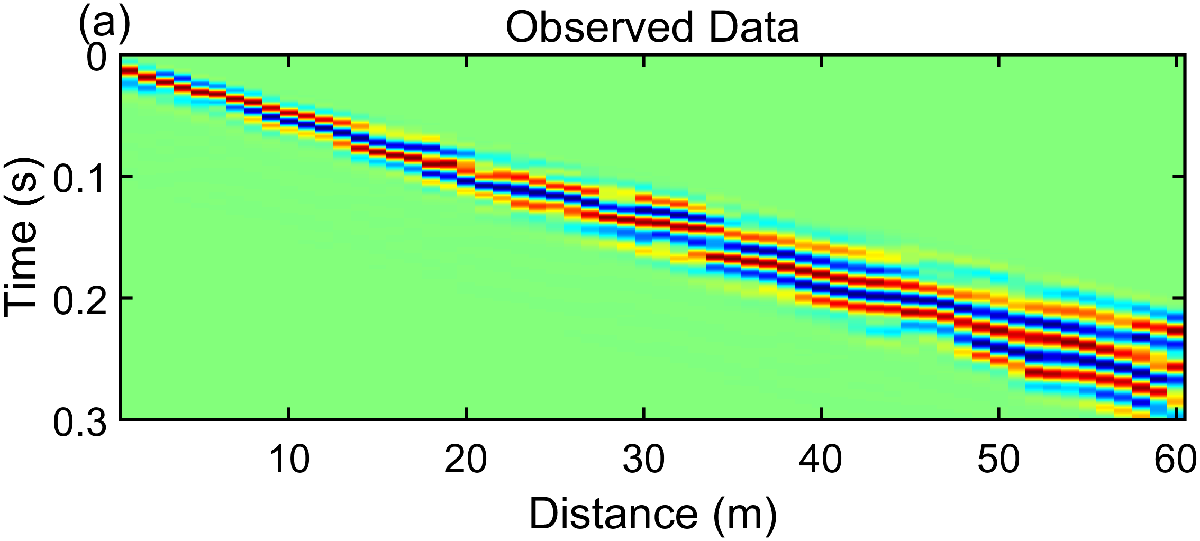

## Extract dispersions

clc;
clear
close all;
load('outcropDisp.mat', 'crl_all_manual')
load('outcropDisp.mat', 'crr_all_manual')
addpath('./core');

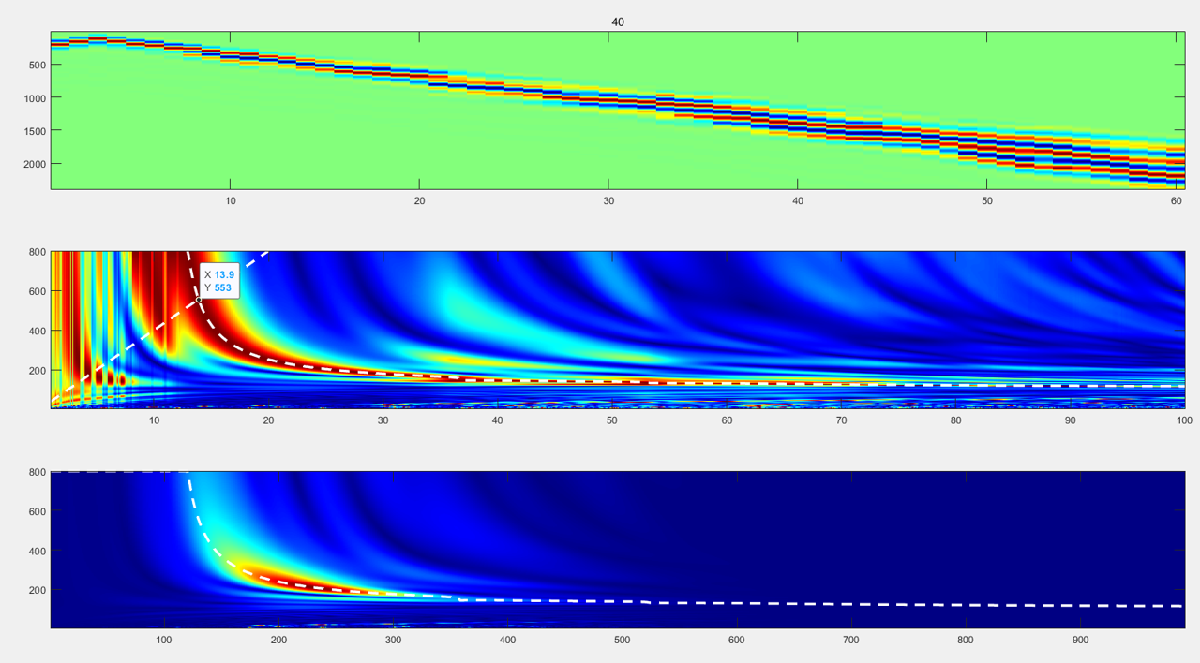

## prapare the data



vsmin=90;vsmax=671*1.6;
vpmin=vsmin*1.732;vpmax=vsmax*1.732;
fr=30;
dx=0.25;%dx=vsmin/fr/12; 150/30/12=0.4167
dt=dx/vpmax*0.5;
dtx=dt/dx;
nz=40;nx=240;
vs = zeros(nz,nx,'single'); % Initial model
for i=1:nx
    vs(:,i)=linspace(150,700,nz);
end
vp=vs*1.732;  % vp is constant


pickMethod=1;  %1==FDC 2==argmax
nt_wf=5;  % Storage wave field interval
nt=floor((nx*dx/min(vs(:))/dt+1000)/10)*10+500;  % time step; Must be divisible by nt_wf
[s,nw]=ricker(fr,dt,nt); s =single(s); % source wavelet
nbc=40;   % boundary layer
% define acquisition geometry
ds=4; sx=single(1:ds:nx); sz=zeros(size(sx),'single')+1;[~,ns]=size(sx);
dg=4;gx=single(1:dg:nx);  gz=zeros(size(gx),'single')+1;  ng=numel(gx);
M=ds/dg;refsx=floor(sx/dg)+1;
dg=dg*dx;  % Randon Transform need real distance
% Set papramters 
pur=-0.05;   % no need to change
offset=50;   % multi-offset &the maximum offset (floor(1.2*nz*dx))
offmin=5;    % no need to change
parameter_type=0;  % no need to change
fd_order=22;fsz=0;source_type='w';  % no need to change
isfs=1;  % no need to change
vmin=100;  % min phase-velocity of RT
vmax=800; % max phase-velocity of RT
np=vmax-vmin+1;  % no need to change
df=0.1;  % no need to change
% fmin=13;  % min freq of the data
fmax=85;  % max freq of the data
ini=200;   % initial point to extract dispersion
m=0;w=4;  % no need to change
err=0.01;  % no need to change
SoftArgNorm = 1e+4;  % no need to change
iteration=100;  % no need to change
smoothZ = 1;smoothX=2;  % change if the gradient is incorrect

## ++++Start SWD iversion ++++

%%--------------------------------------------------------------

parallel_init(ns);  % parallel_init(ns);
vs_all=zeros(nz,nx,iteration); % Save the model of the iteration
dk_vs_all=zeros(nz,nx,iteration); % Save the gradient of the iteration


offsets = zeros(iteration,1);
residual = zeros(iteration,1);





k =1;

while (k<=iteration)  
tic;
display(['Elastic_LSM, k=',num2str(k),' iteration=',num2str(iteration)]);

fmin_all = linspace(20,20,9);fmin_all = [25,fmin_all];
fmin = round(fmin_all(offset/5),1);
ind=fmin/df+1;
freq=(fmin:df:fmax);   
npair=length(freq);
win=npair+2*ind;
space_M = zeros(np,npair);
for i =1:npair
    space_M(:,i) = linspace(1,np,np);
end
fband = round((fmax-1)/df+1);
fstart = round((fmin-1)/df+1);

cr_0 = crr_all_manual(fstart:fband,:,offset/5);
cr_0l = crl_all_manual(fstart:fband,:,offset/5);
% cr_0 = smooth2a(cr_0,1,2);
% cr_0l = smooth2a(cr_0l,1,2);


cr_pre_r = 1.*ones(npair,ns);
cr_pre_l = 1.*ones(npair,ns);
g_cl=zeros(nz,nx);
g_cm=zeros(nz,nx);
g_illum=zeros(nz,nx);

parfor is=1:ns
    [~,seismo_v,wavefield_gradient]=staggerfd_eigen(is,nbc,nt,dtx,dx,dt,sx(is),sz(is),gx,gz,s,vp,vs,isfs,fd_order,source_type,parameter_type,nt_wf);
    seismo_v = norm_trace(seismo_v);
    saveForBackwardr = 0;
    saveForBackwardl = 0;
    if is<=ns-floor(m/M)-round(w/M)
        [mlr,dataLen,saveForBackwardr]=RTrAD(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,nt,ng,dg,offset,m,M); % Cal. the predicetd data dispersion curve for two sides 
        [res_r(is),cr_pre_r(:,is)] = LHDispPick(mlr,vmin,cr_0(:,is),pickMethod,saveForBackwardr);
        saveForBackwardr.cr_r = cr_pre_r(:,is)-vmin;
    end
    
    if is>=round(w/M)+floor(m/M)+1
        [mll,dataLen,saveForBackwardl]=RTlAD(seismo_v,is,df,dt,np,vmin,vmax,fmin,fmax,nt,ng,dg,offset,m,M); % Cal. the predicetd data dispersion curve for two sides 
        [res_l(is),cr_pre_l(:,is)] = LHDispPick(mll,vmin,cr_0l(:,is),pickMethod,saveForBackwardl);
        saveForBackwardl.cr_l = cr_pre_l(:,is)-vmin;
    end
    grad_outputr = cr_pre_r(:,is)-cr_0(:,is);
    grad_outputl = cr_pre_l(:,is)-cr_0l(:,is);
    if offset<11
        [seismo_v_d1]=weight_data_muti3(seismo_v,seismo_v,is,dt,df,offset,dg,0,w,M,m,ns,refsx,win,fmin,fmax, ...
        cr_0(:,is),cr_0l(:,is),cr_pre_r(:,is),cr_pre_l(:,is),ind);% Uncomment there two lines to enable the WD method
    else
    [seismo_v_d1]=ADWDgrad_1(nt,ng,ns,npair,is,w,m,M,SoftArgNorm,grad_outputr,grad_outputl,space_M,saveForBackwardr,saveForBackwardl);% Uncomment this line to enable the SWD method
    end
    %     [seismo_v_d1,res_r]=FWIresidual(seismo_v,seismo_v_d(:,:,is));
    [cl_img,cm_img,illum_div]=e2drtm_eigen(wavefield_gradient,single(seismo_v_d1),is,nbc,nt,dtx,dx,dt,gx,gz,s,vp,vs,isfs,fd_order,parameter_type,nt_wf);
    g_cl = g_cl+cl_img;g_cm = g_cm+cm_img;g_illum = g_illum+illum_div;
end

residual(k)=mean(mean(res_r));%+mean(mean(res_l));
display(['residual = ',num2str( residual(k) ),' k=',num2str(k)]);
res0=residual(k); 
g_cl=g_cl./g_illum;g_cm=g_cm./g_illum;
dk_vs = -4*vs.*g_cl+2*vs.*g_cm;
dk_vs=single(smooth2a(double(dk_vs),smoothZ,smoothX));  % Smooth the Vs gradient

if k==1
    f1=0.5;
end
v_mean=(sum(vs(:).*vs(:)))^0.5;
g_mean=(sum(dk_vs(:).*dk_vs(:)))^0.5;
alpha=v_mean/g_mean*pur;  
display(['v_mean=',num2str(v_mean),' g_mean=',num2str(g_mean),' alpha=',num2str(alpha)]);
vs1=vs+alpha*f1*dk_vs;
vs1(vs1<vsmin)=vsmin;vs1(vs1>vsmax)=vsmax; 
vp = vs1*1.732;

## Result

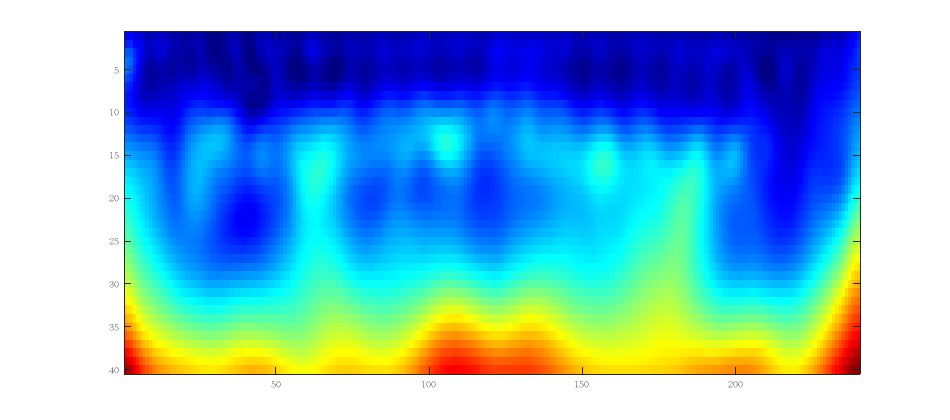

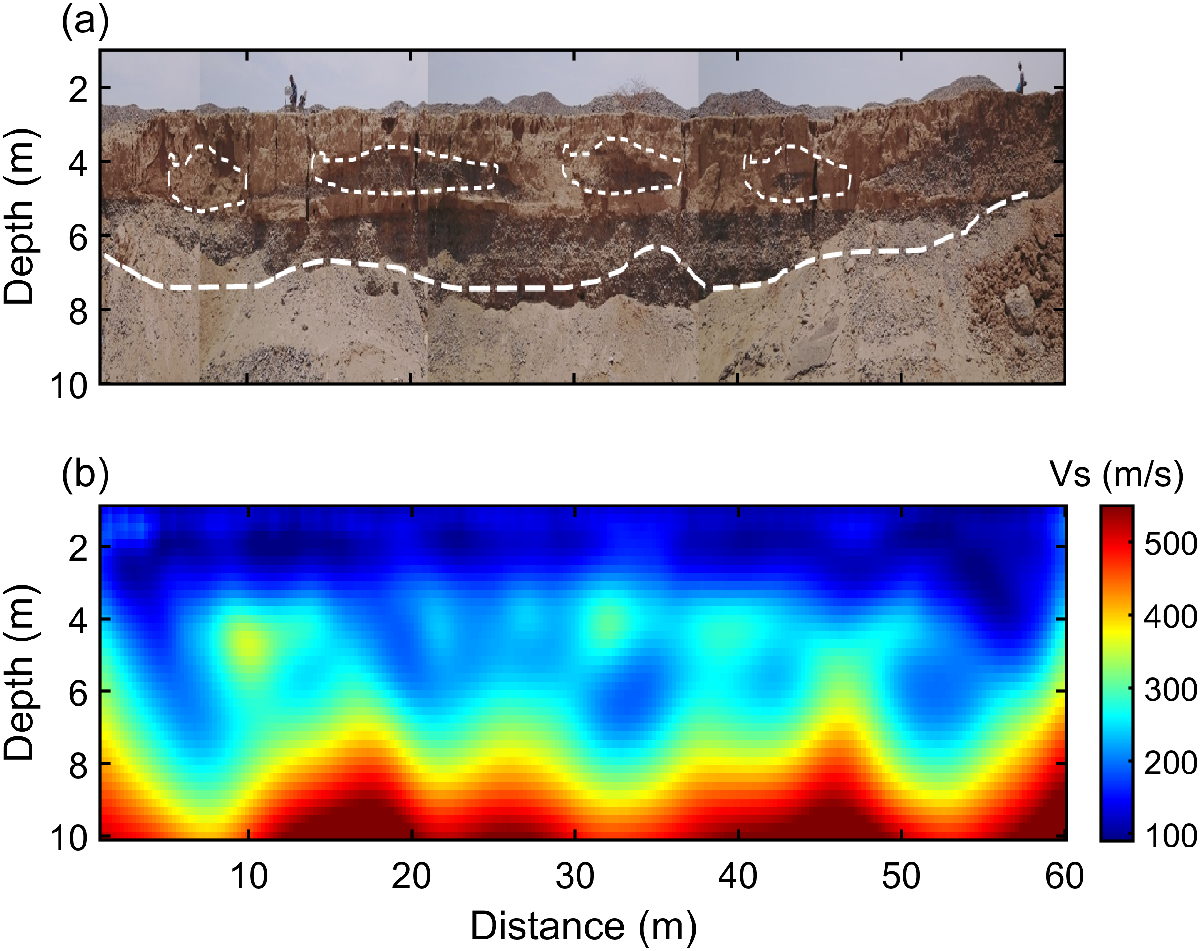

## COG Valid interp

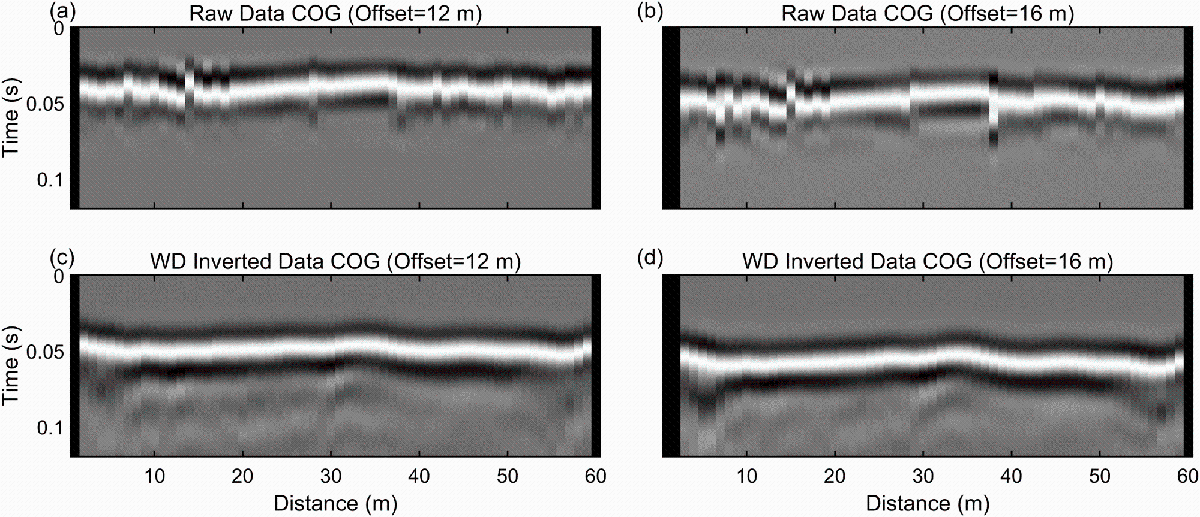

## Disp Valid 

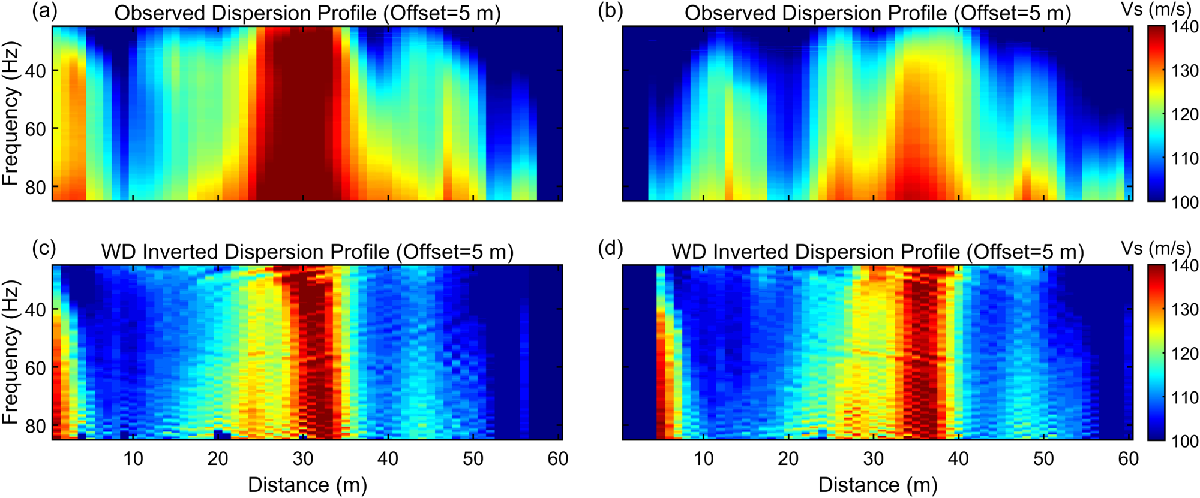

## Misfit